clear
clf
%1st problem (e)

a = 1.115 * 10^-3; %Thermal diffusivity(m^2/s)
U = 50; %Initial temperature (K)
u_o = 10; %Temperature at left boundary u(0,t)
L = 1; %Length of the domain (m)
x = linspace(0,1,1000);

%Time 10
U_1 = 0;
t = 1;
for i = 1:10000
    l = (2*i - 1)*(pi/(2*L));
    A = 2*(U-u_o)/(L*l);
    B = 1 - cos(l*L);
    C = exp(-a*t*(l^2));
    s = sin(l.*x);
    U_1 = U_1 + (A.*B.*C.*s);
    T = U_1 + u_o;
end

U_2 = 0;
t_2 = 10;
for j = 1:10000
    l_1 = (2*j - 1)*(pi/(2*L));
    A_1 = 2*(U-u_o)/(L*l_1);
    B_1 = 1 - cos(l_1*L);
    C_1 = exp(-a*t_2*(l_1^2));
    s_1 = sin(l_1.*x);
    U_2 = U_2 + (A_1.*B_1.*C_1.*s_1);
    T_2 = U_2 + u_o;
end

U_3 = 0;
t_3 = 100;
for k = 1:10000
    l_2 = (2*k - 1)*(pi/(2*L));
    A_2 = 2*(U-u_o)/(L*l_2);
    B_2 = 1 - cos(l_2*L);
    C_2 = exp(-a*t_3*(l_2^2));
    s_2 = sin(l_2.*x);
    U_3 = U_3 + (A_2.*B_2.*C_2.*s_2);
    T_3 = U_3 + u_o;
end

U_4 = 0;
t_4 = 1000;
for m = 1:10000
    l_3 = (2*m - 1)*(pi/(2*L));
    A_3 = 2*(U-u_o)/(L*l_3);
    B_3 = 1 - cos(l_3*L);
    C_3 = exp(-a*t_4*(l_3^2));
    s_3 = sin(l_3.*x);
    U_4 = U_4 + (A_3.*B_3.*C_3.*s_3);
    T_4 = U_4 + u_o;
end

U_5 = 0;
t_5 = 10000;
for n = 1:10000
    l_4 = (2*n - 1)*(pi/(2*L));
    A_4 = 2*(U-u_o)/(L*l_4);
    B_4 = 1 - cos(l_4*L);
    C_4 = exp(-a*t_5*(l_4^2));
    s_4 = sin(l_4.*x);
    U_5 = U_5 + (A_4.*B_4.*C_4.*s_4);
    T_5 = U_5 + u_o;
end

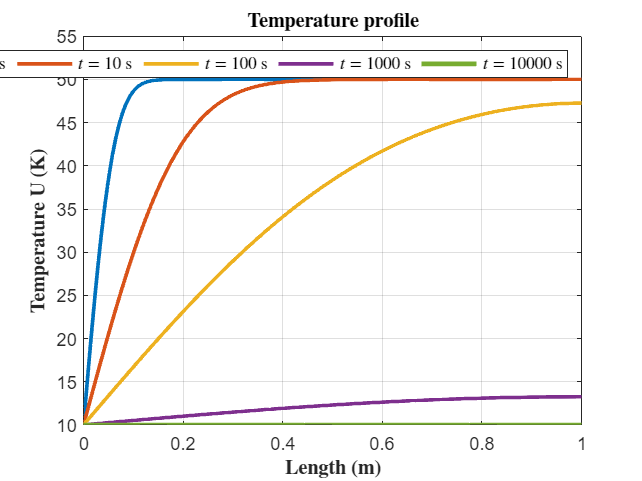

h1 = plot(x,T,'LineWidth',2);
ylabel('$\textbf{Temperature U (K)}$','Interpreter', 'latex')
xlabel('$\textbf{Length (m)}$', 'Interpreter', 'latex')
title('$\textbf{Temperature profile}$', 'Interpreter', 'latex');
grid on
hold on
h2 = plot(x,T_2,'LineWidth',2);
h3 = plot(x,T_3,'LineWidth',2);
h4 = plot(x,T_4,'LineWidth',2);
h5 = plot(x,T_5,'LineWidth',2.5);

legend([h1, h2, h3, h4, h5], '$t = 1$ s','$t = 10$ s', '$t = 100$ s', '$t = 1000$ s', '$t = 10000$ s', 'Orientation', 'horizontal', 'Interpreter', 'latex');

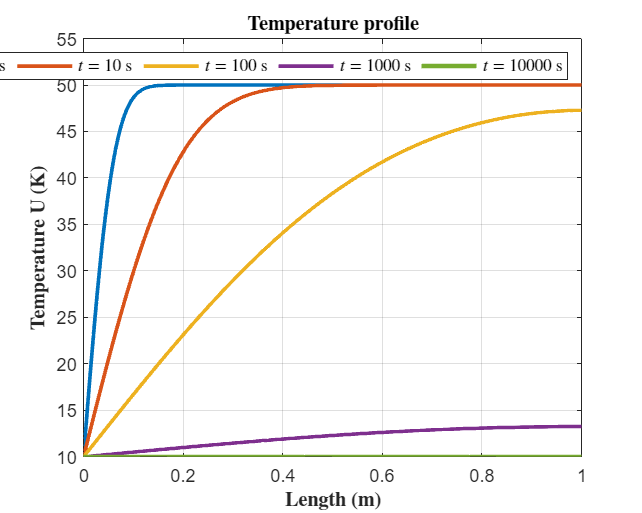

%Saving plot
outputFileName = 'Problem_1_e.png';
figureHandle = gcf;
figureWidth = 1000; % in pixels
figureHeight = 800; % in pixels
set(figureHandle, 'Position', [100, 100, figureWidth, figureHeight]); 
print(figureHandle, outputFileName, '-dpng', '-r600');